# Voxel and image spaces in CANlab fmri_data objects

This brief guide looks at how images are stored as matrices of different dimensions in fmri_data objects. It covers:

- The basics of how to understand the masking procedure, data matrices, and voxel lists in fmri_data objects

- Where space information mapping from matrix to 3-D brain space is stored

- How to **reconstruct** an image into 3-D or 4-D matrix, **resample** one object to the space of another, and **extract data** from regions of interest specified by one object (e.g., an atlas/parcellation) from another (a test image dataset).

When we load a set of images from .nii files, it automatically applies a default "whole brain mask" to save space. 

The rationale is that there's no point in saving empty values outside the brain.

% Load a pre-canned example dataset
imgs = load_image_set('emotionreg', 'noverbose');

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


sampleto = '/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii'

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


This is what the default mask looks like (all the colored voxels are in-mask).

Only values within this mask will be stored in the object.

Setting up fmridisplay objects
sagittal montage: 4895 voxels displayed, 269358 not displayed on these slices
sagittal montage: 4728 voxels displayed, 269525 not displayed on these slices
sagittal montage: 4794 voxels displayed, 269459 not displayed on these slices
axial montage: 38512 voxels displayed, 235741 not displayed on these slices
axial montage: 41445 voxels displayed, 232808 not displayed on these slices


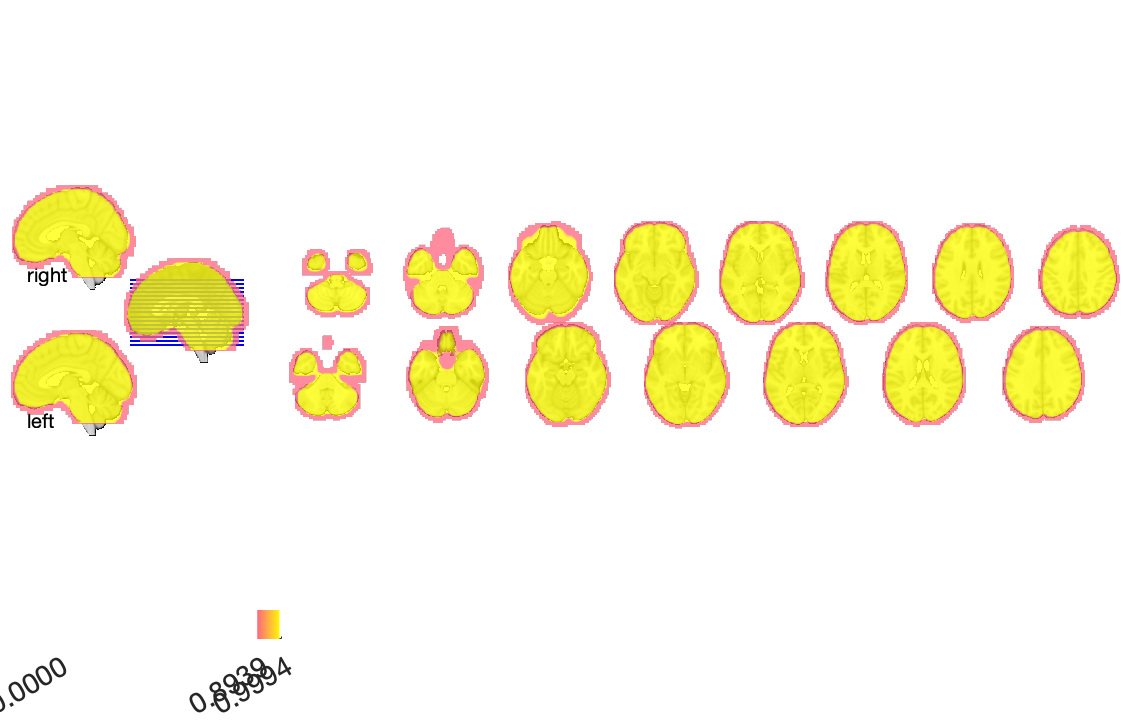

figure; axis off; montage(imgs.mask, 'trans');

The actual image data are stored in the object in the **.dat** field, which is a matrix of **[voxels x images]** dimension.  Here, we have **[31686 in-mask voxels x 30 images] **stored in the object:

size(imgs.dat)  

ans =       352328          30


### Voxel sets associated with the image object

There are three sets of voxels associated with the image object:

- The **entire image** set of *E* voxels 

- The **"in-mask"** set of *M *voxels (excluding voxels outside the mask used when creating the image)

- The **"data list"** set of *V* voxels (excluding voxels with missing/empty values (0 or NaN) for all images

The rationale is that we don't need to save values for thousands of voxels if they are empty in all images. (0 or NaN, zero is coded as missing/empty).  

The method ***remove_empty( ) ***finds and removes voxels empty in all images, and stores a logical indicator for which were removed in the **.removed_voxels **field.  Before running this, the **.dat **field has a data matrix of [*M* x number_of_images].  After running, the **.dat **field now has a data matrix of [*V* x number_of_images].The  **.removed_voxels **field is [*M* x 1].

The method ***replace_empty( ) ***uses the the **.removed_voxels **field to reconstruct the **.dat **field to the original [*M* x number_of_images]. Empty voxels are filled in with zeros in all images.

Sometimes, it's advantageous to work only with the "data list", where the data matrix has at least one valid value for each voxel.  Other times, as when you're matching up images to apply a mask or concatenate data, you need the full set of *M* voxels in the original mask.  

Finally, other times you may need a dataset with one value for the entire set of *E* voxels in the image. It's not possible to recover values outside the mask, as they were omitted during object creation.  However, you can use the method **reconstruct_image **to reconstruct the entire 3-D  (for an object with one image) or 4-D (for an object with multiple images) data matrix. This fills empty values with zero.  Then, you can vectorize this 3-D or 4-D matrix.

### The** .volInfo** field stores voxel and image space information

The** .volInfo** field has information aboutt the mask, space, voxel sizes, origin, and transformations from "image" (voxel) to "world" (mm) space.  

imgs.volInfo

ans = struct with fields:
         fname: 'REMOVED: CHANGED SPACE'
           dim: [47 56 31]
            dt: [16 1]
         pinfo: [3×1 double]
           mat: [4×4 double]
             n: [1 1]
       descrip: 'Space of /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii'
       private: [1×1 nifti]
          nvox: 81592
    image_indx: [81592×1 logical]
     wh_inmask: [35676×1 double]
      n_inmask: 35676
       xyzlist: [35676×3 double]
       cluster: [35676×1 double]


**imgs.volInfo.mat **contains the matrix with the origin (zero point in mm), voxel sizes, and any rigid-body rotations applied to the image. This is the same format as used by SPM and stored in SPM ".mat" files.

imgs.volInfo.mat

ans =    -3.4375         0         0   82.5000
         0    3.4375         0 -116.8750
         0         0    4.5000  -54.0000
         0         0         0    1.0000


- Here, the voxel size is 3.4375 and the origin is [82.5000 -116.8750  -54.0000].

- The negative sign of the first element (-3.4375) indicates that the images were stored in "radiological format" and flipped left-right when loading them from disk to store them in "neurological format" (right side of image is right side of brain) in the object.

- The zeros in the off-diagonals indicate that there were no rotations applied when loading the images from .nii/.img 

- The bottom right element (4, 4) is the SPM scaling factor, also applied when loading the images from .nii/.img 

You shouldn't have to worry about these much, as the object methods should handle them "under the hood". But sometimes it's valuable to know.

**imgs.volInfo.dim **contains the 3-D dimensions of the image in voxels, in x (left-to-right), y (back-to-front), and z (bottom-to-top).  

imgs.volInfo.dim

ans =     47    56    31


**imgs.volInfo.xyzlist** contains a list of the voxel coordinates [x y z] for each in-mask voxel (an [*M* x 3] matrix)

and **imgs.volInfo.cluster **contains an [*M* x 1] integer vector, where the integers represent contiguous "blobs" estimated with *spm_cluster.m.  *

These are used in various operations, including the transformation of an **fmri_data** object into a **region**-class object (with *region( )*),which stores data grouped by contiguous region.  

imgs.volInfo.xyzlist(1:5, :)

ans =     18     9     1
    19     9     1
    28     9     1
    29     9     1
    30     9     1


imgs.volInfo.cluster(1:5, :)

ans =      1
     1
     1
     1
     1


### An example looking at the number of voxels in each voxel list

Let's take a look at our example:

- Here there are 81,592 voxels in the entire image (E), including "out of mask" voxels

- There are 35,676 "in-mask" voxels (M)

- We start off with 35,676 voxels in the "data list"

% 81592 in the entire image, including "out of mask" voxels
imgs.volInfo.nvox 

ans = 81592


% 35676 in the brain mask (with possible data, but some voxels may be empty)
imgs.volInfo.n_inmask

ans = 35676


% 35676 voxels in the data list in .dat
size(imgs.dat, 1)  

ans = 35676

Now we'll use remove_empty to exclude empty/missing voxels from the data list.

We still have 35,676 voxels in the "data list" because the images contain values for all these voxels.

% 35676 voxels with non-empty valid data (non-zero, non-nan) for at least 1 image
imgs = remove_empty(imgs);
size(imgs.dat, 1)  

ans = 35676

### **Masking**

Now we'll apply a gray-matter mask, excluding voxels in the ventricles and gray matter, which will be removed from the image object.  These values are discarded, so we can't recover them later.

imgs = apply_mask(imgs, which('gray_matter_mask.nii'));

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


Setting up fmridisplay objects
sagittal montage: 1103 voxels displayed, 30583 not displayed on these slices
sagittal montage: 1061 voxels displayed, 30625 not displayed on these slices
sagittal montage: 1010 voxels displayed, 30676 not displayed on these slices
axial montage: 10380 voxels displayed, 21306 not displayed on these slices
axial montage: 10986 voxels displayed, 20700 not displayed on these slices


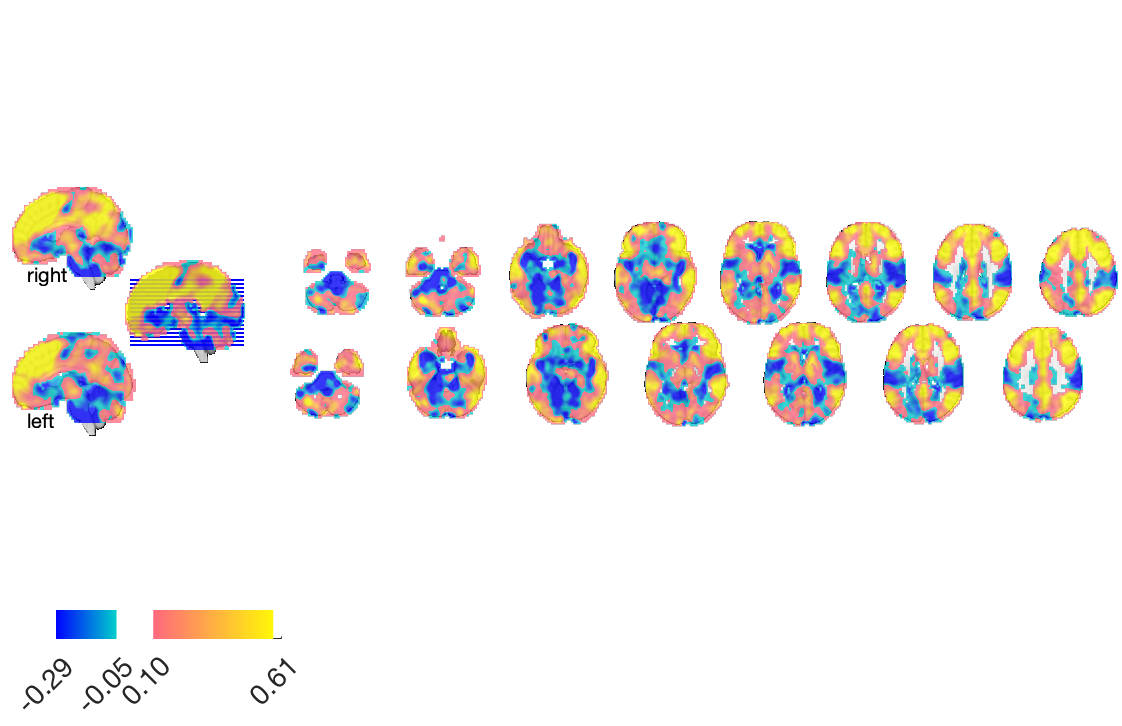


figure; axis off; montage(mean(imgs), 'trans');

Now, we have a reduced number of voxels with valid data, as we've masked some out:

size(imgs.dat) % now we have only 31,686 voxels with data because we have masked some out

ans =        31686          30



length(imgs.removed_voxels) % this is still the length of the original mask

ans = 35676

The sum of the removed_voxels logical vector reflects the number removed. The number removed and the number remaining must always sum to M (number in mask) for any valid object:

sum(imgs.removed_voxels) % this is how many voxels are excluded from current imgs.dat

ans = 3990

size(imgs.dat, 1) + sum(imgs.removed_voxels) % current voxels + removed must = total number of voxels in mask

ans = 35676

### Resampling

Resampling uses the volInfo.mat field to calculate the rotations and interpolation (i.e., changes in voxel size) needed to sample an image object into the same space as a reference image object, so that all the voxels line up (i.e., are located at the same brain coordinates) across objects.

This is essential when applying masks, patterns, and atlas regions of interest, and when concatenating data for analysis of combined datasets.

Resampling is often done "under the hood" when you use various methods, like **apply_mask( ) **or **cat( ).**

Let's load an **atlas-class** object with a number of regions of interest (489 ROIs) and resample our dataset to that atlas, so the voxels line up with the atlas labels:

atl = load_atlas('canlab2018_2mm');

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


imgs = resample_space(imgs, atl);

imgs.volInfo.nvox

ans = 902629

size(imgs.dat)

ans =       352328          30


Now there are 902,629 voxels in the entire image (E) and 352,328 voxels in the mask (M). This matches the list in the atlas object.

### Extracting data from matched objects

Since the voxels match in location across the dataset object (imgs) and atlas (atl), we can identify voxels in any given region of the atlas, and simply grab those from the .dat field in the imgs object.

% select an arbitrary region from the atlas, #23, which is area 55b
wh_vox = atl.dat == 23;  
atl.labels{23}

ans = 'Ctx_55b_L'


% get the [voxels x images] matrix of data from our test dataset, for
% voxels in area 55b
roi_data = imgs.dat(wh_vox, :);
whos roi_data

  Name            Size            Bytes  Class     Attributes

  roi_data      340x30            81600  double              



There are other ways of extracting data as well. This example is just to illustrate voxel lists and spaces. 

Some other methods include:

**select_atlas_subset(atl) ** to get one or more regions by name or number from the atlas object

**extract_roi_averages(imgs, atl)** to get ROI averages or pattern expression data from all the regions in the atlas.

**data_table = extract_data(atl, imgs)** to do the same (this is an atlas-object method)

** extract_roi_averages(atl, imgs)** to do the same (this is an atlas-object method)

**DAT = extract_measures_batch(imgs);**  to extract a bunch of signature pattern responses and  ROI means from several parcellations.  